#     Getting Started with the ANACONDA_2 Coincidence data analysis toolbox

## Description

ANACONDA allows the analysis of data recorded in experiments that use single-particle detectors (e.g. ions, electrons, photons ...), for example to study the correlation between these particles. These are often called `[coincidence](https://www.sciencedirect.com/science/article/pii/S0368204815001310)' spectrocopic treatment methods. In contrast to other software packages, this package loads the entire measurement to RAM for analyses. This speeds up the treatment and visualization considerably.

## System Requirements

Matlab version R2016b or higher

## Features

The package contains macros to correct, convert, filter, plot and fit the data from multi-detector experiments. The filters allow cross-detector correlation5 analysis to be performed. 

## Examples

Below is a short example of data import, followed by correction, conversion, and the application of filters.

**Data**

There are many types of experimental setups that perform coincidence measurements. Most of them export to different file formats. This package supports a few formats: the ASCII export from the IGOR acquisition software of EPICEA (Soleil/Pleiades experimental setup), ASCII export from CoboldPC (Roentdek acquisition software) and the import of DLT files (Labview acquisition file format, Erik Mansson). If you want to import yet another data format, you can see below what the final format should be for the package to read it. Here, we load some example (dummy) COBOLD PC data into memory:

%data = IO.COBOLD.import_example()
% In case you want to open your own file (.dlt, or .txt from LMF, or HDF5:
try data = IO.import_raw('./Documents/Lund/HDF5_example/Ar_BMon_noB_260eV_vmi_like_singlebunch_1.hdf5');
catch data = IO.COBOLD.import_example();
end

As you can see, the data is stored in the form of a structure, with 'e' and 'h' as fields. 'e' stands for events, and 'h' for hits. The hits contain the raw data (for example, detection position and time), of each detector. For example for detector 1, we have:

data.h.det1

ans = struct with fields:
    raw: [316058×3 double]


**Metadata**

We need to know more *about* this data to start data treatment. For example, we need to know what this 'raw' data contains. This kind of information is stored in a separate 'metadata' file. Each datafile must contain such a file (habitually in the same folder as the data, with the same name except the prefix 'md_' and extension '.m'). Metadata is literally 'data about the data', and the package uses the metadata to find out how to deal with information. Let's load such metadata:

mdata = metadata.defaults.exp.CIEL.md_all_defaults

mdata = struct with fields:
    sample: [1×1 struct]
    photon: [1×1 struct]
      spec: [1×1 struct]
       det: [1×1 struct]
      corr: [1×1 struct]
     calib: [1×1 struct]
      conv: [1×1 struct]
      cond: [1×1 struct]
      plot: [1×1 struct]
       fit: [1×1 struct]


This metadata is a default configuration of the experimental setup CIEL. We can for example read what the data signals are of detector 1:

mdata.det.det1.signals

ans = 1×3 cell array
    {'X [mm]'}    {'Y [mm]'}    {'TOF [ns]'}


So, the first two columns contain position information ('X' and 'Y'), and the third one the time of detection (TOF, or 'Time Of Flight').

With the use of this metadata, the data can be treated in so-called 'macros', such as 'correct', 'convert', 'filter'. We perform a correction here of a shift in X and Y coordinates of all detections of detector 1:

data_XYshifted = macro.correct.dXdY(data, mdata, 'det1');

Log: Detector image translation correction performed on det1


There are many of these corrections or conversions. The corrections take the raw (in this case X,Y,TOF) output from the detector and form them into variables X, Y, and TOF, with possible corrections needed. The conversion macros then use these signals to calculate extra signals, such as mass, momentum, energy, etcetera. The corrections can all be performed in one command:

data_corrected = macro.correct(data, mdata);

Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2
Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: delta TOF correction performed on det1


It is stored in the metadata which corrections or conversions will be performed. For example, the corrections on detector two that are requested:

mdata.corr.det2.ifdo

ans = struct with fields:
           dXdY: 1
         dTheta: 1
           dTOF: 1
    detectorabb: 0
        lensabb: 0


The conversions can all be called from the following macro:

data_converted = macro.convert(data_corrected, mdata)

Log: momentum conversion performed on det1
Log: m2q conversion performed on det1
Log: the convert macro called m2q_label failed to run on det1
Log: the convert macro called KER failed to run on det1
Log: R, theta conversion performed on det1
Log: the convert macro called PolarPxPz failed to run on det1
Log: the convert macro called PolarPyPz failed to run on det1
Log: the convert macro called PolarPxPyPz failed to run on det1
Log: m2q conversion performed on det2
Log: the convert macro called m2q_label failed to run on det2
Log: the convert macro called momentum failed to run on det2
Log: the convert macro called KER failed to run on det2


data_converted = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


**Plots**

After correction and conversion of the data, we can show some histograms. The quickest way is to make a histogram of the hits on a detector, for example the X versus the Y position:

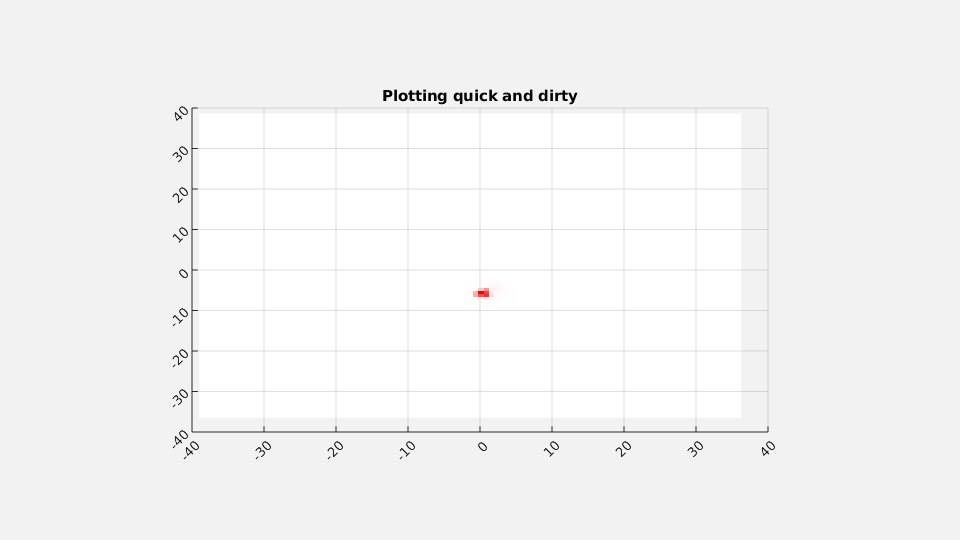

h_fig = plot.quickhist([data_converted.h.det1.X, data_converted.h.det1.Y], 'axes.Title.String', 'Plotting quick and dirty');

It would however require a lot of text to make this figure look decent. Therefore, the metadata also holds information on which kind of plots to make. A plot is constructed of 'signals', for example the X position we plotted above:

mdata.plot.signal.i_X.hist, 

ans = struct with fields:
    pointer: 'h.det2.X'
    binsize: 0.2500
      Range: [-30 30]


mdata.plot.signal.i_X.axes

ans = struct with fields:
      Lim: [-30 30]
     Tick: [-40 -32 -24 -16 -8 0 8 16 24 32 40]
    Label: [1×1 struct]


These signals can be combined into a plot. To give a short example, we can construct plot metadata of the same data as above, but from the plot signals:

XY_plot_md = metadata.create.plot.signal_2_plot({mdata.plot.signal.i_X, mdata.plot.signal.i_Y});

We can also add a title:

XY_plot_md.axes.Title.String = 'Plotting with the macro'

XY_plot_md = struct with fields:
      figure: [1×1 struct]
        axes: [1×1 struct]
        hist: [1×1 struct]
    GraphObj: [1×1 struct]


And we can create a plot from that:

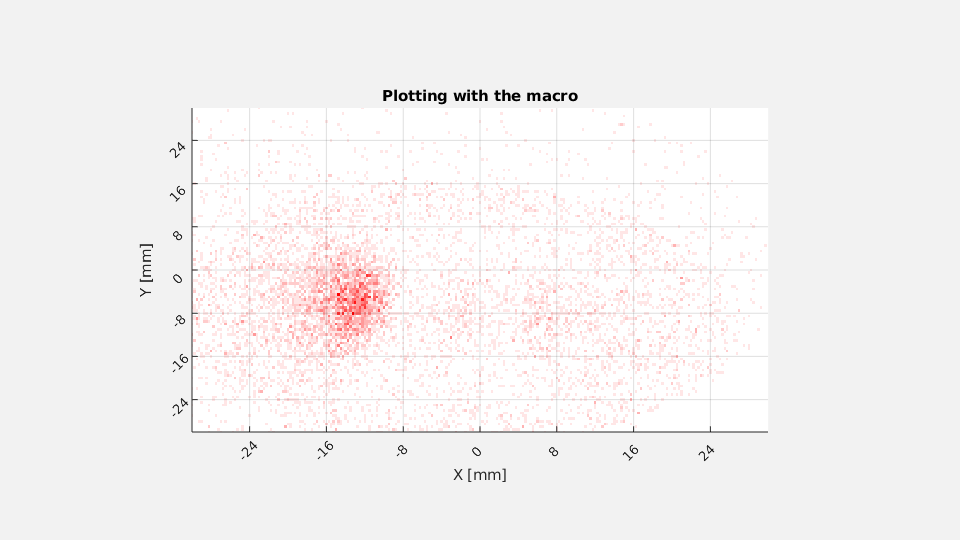

macro.plot.create.plot(data_converted, XY_plot_md);

Note that there are many such plot metadata already defined in the metadata files. If you want to see them, find them in:

mdata.plot.det1;

Or see how thery are defined in the metadata files.

**Conditions and filters**

The strength of coincidence measurements is to select a portion of the data that is of highest interest. For example, we might want to only look at the most central part of the X,Y plot. This can be achieved by imposing 'conditions' on the shown signals. A condition can be seen as a statement, for example: '*We only want to see data that resulted in detections on detector 2 within a square of 8x8mm around the center*'. We have defined such a condition already in the metadata:

mdata.cond.i_XY.X,

ans = struct with fields:
                   type: 'continuous'
           data_pointer: 'h.det2.X'
                  value: [-8 8]
    translate_condition: 'AND'
          invert_filter: 0


mdata.cond.i_XY.Y,

ans = struct with fields:
                   type: 'continuous'
           data_pointer: 'h.det2.Y'
                  value: [-8 8]
    translate_condition: 'AND'
          invert_filter: 0


mdata.cond.i_XY.X.value =  [-4 4];
mdata.cond.i_XY.Y.value =  [-4 4];

We need to explain the fields: *type *can be two options: 'discrete' means that there are only a few discrete values that can be approved, 'continuous' means that a minimum and maximu is given in between the signal must be. *data_pointer* is the signal (or combination of signals) the condition should read. *value* are the values that the signal should be (in the case of 'discrete' type), or where it should be within (in the case of 'continuous' type). In this case, we have assigned a hit signal in the data pointer. Internally, ANACONDA always calculates an event condition, and the *translate condition* tells the filter all hits in one event should be approved ('AND'), or only one of them ('OR'). Optionally, the hit number can be specified. If one only wants to see the first hit, 'hit1' is the right translate condition, etcetera for hit2,3. Lastly, there is the option to invert a condition/filter: all events that follow the condition are left out, and vice versa.

Now we will apply this condition to the data, to construct a 'filter':

event_filter = macro.filter.conditions_2_filter(data_converted, mdata.cond.i_XY);

Reference to non-existent field 'raw'.

Error in macro.filter.conditions_2_filter>C2F (line 57)
	events          = exp_data.e.raw;

Error in macro.filter.conditions_2_filter (line 51)
	[f, exp_data] = C2F(exp_data, conditions);

We can plot the histogram with this condition and verify its action:

XY_plot_md.cond = mdata.cond.i_XY;
XY_plot_md.axes.Title.String = 'Plotting with the condition applied (detector 2)'
macro.plot.create.plot(data_converted, XY_plot_md);

We can investigate the effect of this filter on detector 1. 

theta_R = mdata.plot.det1.theta_R;
theta_R.axes.Position = [0.1 0.2 0.35 0.6];
theta_R.axes.Title.String = 'No condition applied (detector 1)'
[h_fig_no_filter, h_ax_no_filter]     = macro.plot.create.plot(data_converted, theta_R);
theta_R.axes.Title.String = 'Condition applied (detector 1)'
theta_R.cond = mdata.cond.i_XY;
theta_R.axes.Position = [0.55 0.2 0.35 0.6];
[h_fig_no_filter, h_ax_filter]      = macro.plot.create.plot(h_fig_no_filter, data_converted, theta_R);


The filter thus acts on detector 2, while we use it to show a difference in the data on detector 1. 